n = -40:1:40;
t = -40:0.01:40

t =   -40.0000  -39.9900  -39.9800  -39.9700  -39.9600  -39.9500  -39.9400  -39.9300  -39.9200  -39.9100  -39.9000  -39.8900  -39.8800  -39.8700  -39.8600  -39.8500  -39.8400  -39.8300  -39.8200  -39.8100  -39.8000  -39.7900  -39.7800  -39.7700  -39.7600  -39.7500  -39.7400  -39.7300  -39.7200  -39.7100  -39.7000  -39.6900  -39.6800  -39.6700  -39.6600  -39.6500  -39.6400  -39.6300  -39.6200  -39.6100  -39.6000  -39.5900  -39.5800  -39.5700  -39.5600  -39.5500  -39.5400  -39.5300  -39.5200  -39.5100



% Create the unit step function
u = @(a) (a>=0);
d = @(a) (a==0);

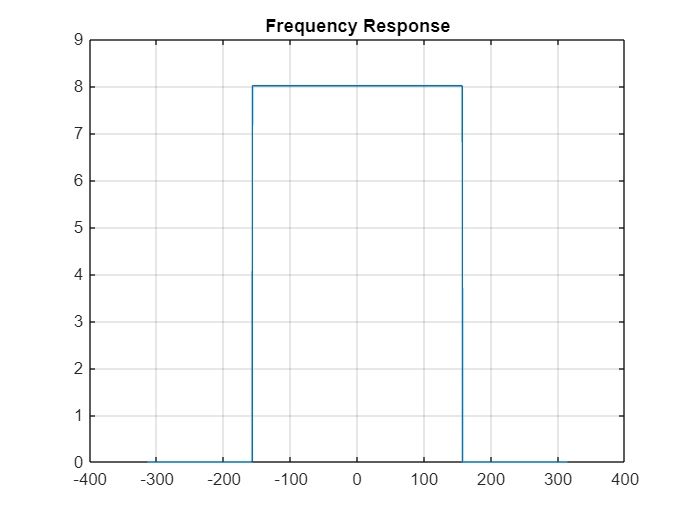

%Randoms

clear
clc
M = 128;
dt = 0.01;
Fs = 1/dt;
t = -8:dt:8;
L = length(t);
w = 2*pi*linspace(-Fs/2,Fs/2,L);
Hw = zeros(size(w));
ut4 = t>=-4;
ut_4 = t>=4;
ht = 0.5*(ut4-ut_4);
for k = 1:length(w)
    Hw = Hw+exp(-j*w.*t).*ht;
end
Hw = dt*Hw;
figure(1)
plot(w,abs(Hw))
title('Frequency Response')
grid on

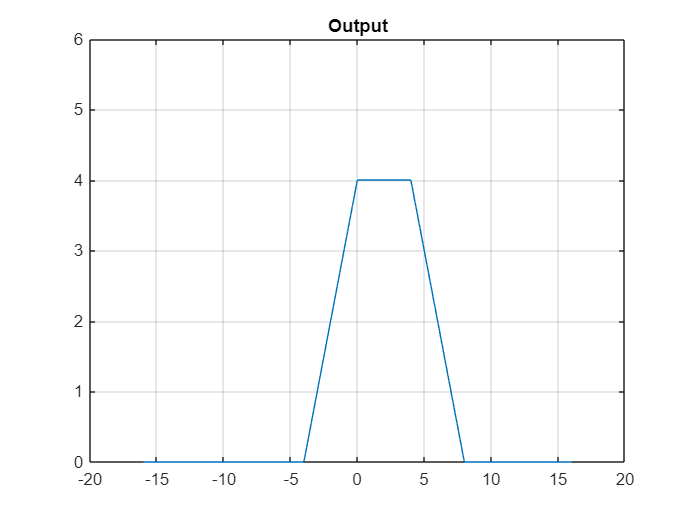


ut = t>=0;
xt = 2*(ut-ut_4);
yt = conv(xt,ht)*dt;
tt = -2*8:dt:2*8;
figure(2)
plot(tt,yt)
title('Output')
ylim([0 6])
grid on












po = @(a) a.*(u(a)-u(a-1))-(a-2).*(u(a-1)-u(a-2));
p = @(a) (a-2).*(u(a-3)-u(a-2))-(a-4).*(u(a-4)-u(a-3));

plot(t,p(t),'LineWidth',2)

Unrecognized function or variable 'u'.

Error in Copy_of_Tests>@(a)(a-2)*(u(a-3)-u(a-2))-(a-4)*(u(a-4)-u(a-3)) (line 45)
p = @(a) (a-2)*(u(a-3)-u(a-2))-(a-4)*(u(a-4)-u(a-3));

ylim([-4.00 4.00])
xlim([-2.00 5.00])
ylabel('x(n)')
xlabel('time n')
grid on


% Even Odd

x = @(b) d(b + 2) + d(b - 3);

plot(t,x(t),'LineWidth',1)
ylim([-1.5 5.5])
xlim([-4.00 5.00])
ylabel('x(n)')
xlabel('time n')
grid on

plot(t,odd(x, t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-8.00 8.00])
ylabel('xo(n)')
xlabel('time n')
grid on

plot(t,even(x, t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-8.00 8.00])
ylabel('xe(n)')
xlabel('time n')
grid on

% 5
totalEnergy = sum(abs(x(t)).^2)

% 6
oddEnergy = sum(abs(odd(x, t)).^2)
evenEnergy = sum(abs(even(x, t)).^2)
oddEnergy + evenEnergy
% oddEnergy + evenEnergy = totalEnergy





x1 = @(b) b.*(u(b) - u(b-5));
x2 = @(b) 4*(u(b-5) - u(b-11));
x3 = @(b) -2*d(b-8);

x = @(b) u(b + 1) - u(b - 3);

% 2
stem(n,x1(n),'LineWidth',1)
ylim([-3 7.50])
xlim([-4.00 10.00])
ylabel('x1(n)')
xlabel('time n')
grid on

stem(n,x2(n),'LineWidth',1)
ylim([-1.5 5.5])
xlim([0.00 16.00])
ylabel('x2(n)')
xlabel('time n')
grid on

stem(n,x3(n),'LineWidth',1)
ylim([-3.5 3.5])
xlim([0.00 10.00])
ylabel('x3(n)')
xlabel('time n')
grid on

stem(n,x(n),'LineWidth',1)
ylim([-1.5 5.5])
xlim([-4.00 8.00])
ylabel('x(n)')
xlabel('time n')
grid on

% 3
stem(n,odd(x, n),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-8.00 8.00])
ylabel('xo(n)')
xlabel('time n')
grid on

% 4
stem(n,even(x, n),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-8.00 8.00])
ylabel('xe(n)')
xlabel('time n')
grid on

% 5
totalEnergy = sum(abs(x(n)).^2)

% 6
oddEnergy = sum(abs(odd(x, n)).^2)
evenEnergy = sum(abs(even(x, n)).^2)
oddEnergy + evenEnergy
% oddEnergy + evenEnergy = totalEnergy




function comp = odd(funct, in) % ang must be in rad; returns in rad
    comp = (funct(in)-funct(-in))/2;
end

function comp = even(funct, in) % ang must be in rad; returns in rad
    comp = (funct(in)+funct(-in))/2;
end